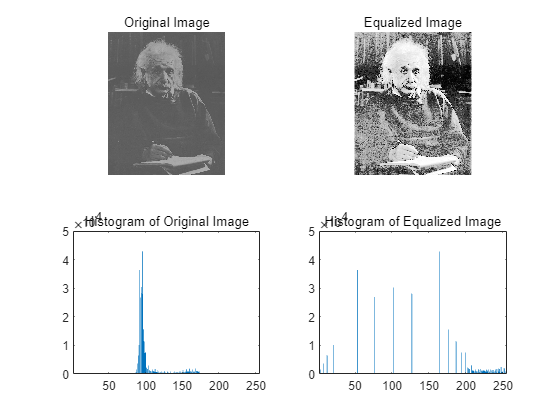

% Load the image
img = imread('images/einstein_low_contrast.tif');

% Compute the histogram
num_bins = 256;
histogram = zeros(1, num_bins);
for i = 1:size(img,1)
    for j = 1:size(img,2)
        intensity = img(i,j) + 1; % add 1 to start bin count from 1
        histogram(intensity) = histogram(intensity) + 1;
    end
end

% Perform histogram equalization
num_pixels = size(img,1) * size(img,2);
cumulative_hist = cumsum(histogram) / num_pixels;
equalized_img = zeros(size(img), 'uint8');
for i = 1:size(img,1)
    for j = 1:size(img,2)
        intensity = img(i,j) + 1; % add 1 to start bin count from 1
        equalized_intensity = round(cumulative_hist(intensity) * (num_bins - 1));
        equalized_img(i,j) = equalized_intensity;
    end
end

% Compute the histogram of the equalized image
equalized_histogram = zeros(1, num_bins);
for i = 1:size(equalized_img,1)
    for j = 1:size(equalized_img,2)
        intensity = equalized_img(i,j) + 1; % add 1 to start bin count from 1
        equalized_histogram(intensity) = equalized_histogram(intensity) + 1;
    end
end

% Display the original image, equalized image, and their histograms
subplot(2,2,1);
imshow(img);
title('Original Image');
subplot(2,2,2);
imshow(equalized_img);
title('Equalized Image');
subplot(2,2,3);
bar(histogram);
xlim([1, num_bins]);
title('Histogram of Original Image');
subplot(2,2,4);
bar(equalized_histogram);
xlim([1, num_bins]);
title('Histogram of Equalized Image');